# SNW_PARAM Tiny Solution Analysis

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**snw_vfi_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_vfi_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for policy function fully iteratively using matlab minimizer.

## Test SNW_VFI_MAIN Defaults

Call the function with defaults.

mp_param = snw_mp_param('default_tiny');
[V_VFI,ap_VFI,cons_VFI,exitflag_VFI] = snw_vfi_main(mp_param);

Finished Age Group:7 of 7
Finished Age Group:6 of 7
Finished Age Group:5 of 7
Finished Age Group:4 of 7
Finished Age Group:3 of 7
Finished Age Group:2 of 7
Finished Age Group:1 of 7
Elapsed time is 67.846941 seconds.


## Tiny Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 28:16:92, 100];
agrid = mp_param('agrid')';
eta_grid = mp_param('eta_grid')';
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_param('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'shock', eta_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Savings and Shocks

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 3; % how many shock legends to show
mp_support_graph('st_rounding') = '6.2f'; % format shock legend

#### MEAN(VAL(A,Z)), MEAN(AP(A,Z)), MEAN(C(A,Z))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(A,Z))", V_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mn_shock__1_4213    mn_shock__0_71067    mn_shock_0    mn_shock_0_71067    mn_shock_1_4213
    _____    ________    ________________    _________________    __________    ________________    _______________

      1             0        -4.6423              -3.9293            -3.092          -2.0638           -0.90014    
      2      0.068587        -4.3299              -3.6876           -2.8958          -1.8965           -0.75175    
      3        0.5487        -3.0852              -2.6304           -1.9817          -1.1778           -0.13595    
      4        1.8519        -1.3933              -1.1296          -0.70319        -0.063849            0.74405    
      5        4

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(A,Z))", ap_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mn_shock__1_4213    mn_shock__0_71067    mn_shock_0    mn_shock_0_71067    mn_shock_1_4213
    _____    ________    ________________    _________________    __________    ________________    _______________

      1             0       0.0042292            0.0089452         0.047396         0.13258             0.34511    
      2      0.068587        0.016583             0.025316         0.073652         0.15592             0.38331    
      3        0.5487         0.22027              0.25771          0.30952         0.37217             0.61517    
      4        1.8519         0.85076              0.88233          0.95457          1.1057              1.1837    
      5        4.

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(A,Z))", cons_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mn_shock__1_4213    mn_shock__0_71067    mn_shock_0    mn_shock_0_71067    mn_shock_1_4213
    _____    ________    ________________    _________________    __________    ________________    _______________

      1             0        0.22088              0.29663          0.41556          0.64367             1.0617     
      2      0.068587        0.28149              0.35316          0.46216          0.69317             1.0963     
      3        0.5487        0.58839              0.63098          0.73627          0.98675             1.3742     
      4        1.8519         1.3429               1.3907            1.475           1.6367             2.1891     
      5        4.3

Graph Mean Values:

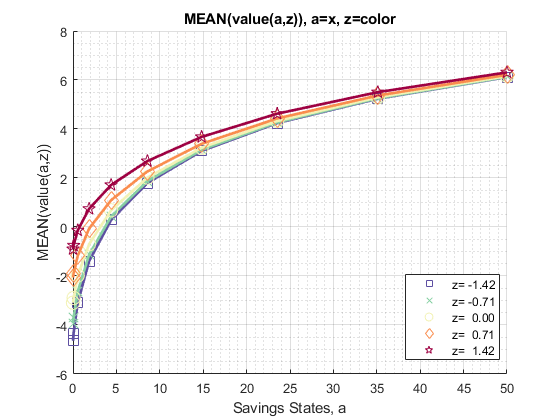

mp_support_graph('cl_st_graph_title') = {'MEAN(value(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

Graph Mean Savings Choices:

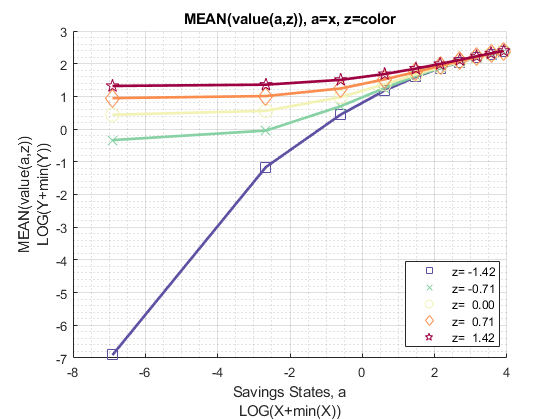

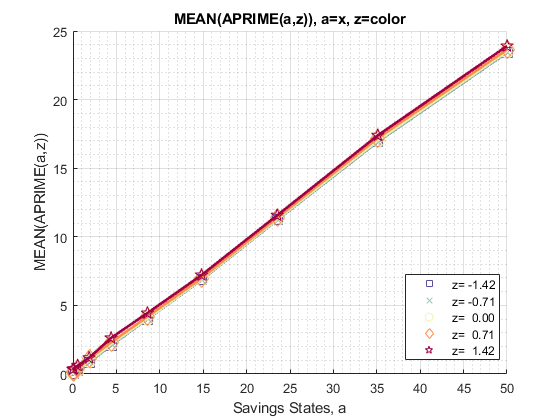

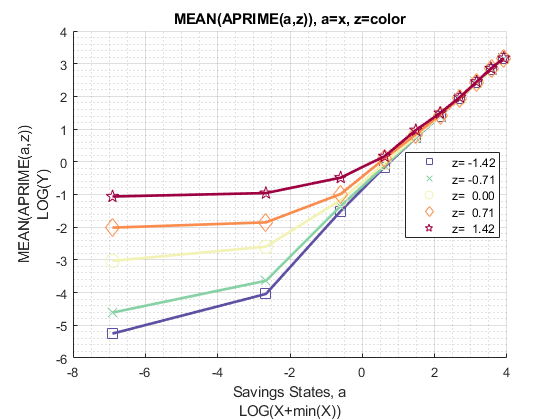

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(a,z))'};
ff_graph_grid((tb_az_ap{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

Graph Mean Consumption:

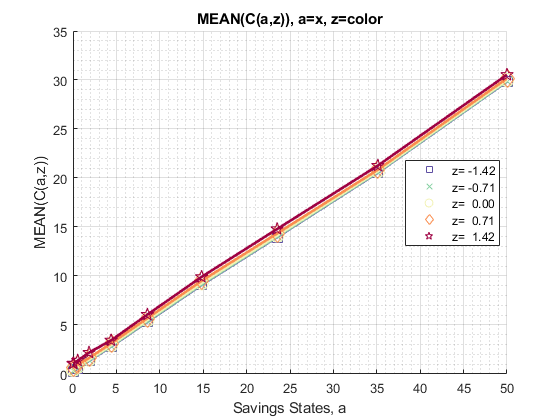

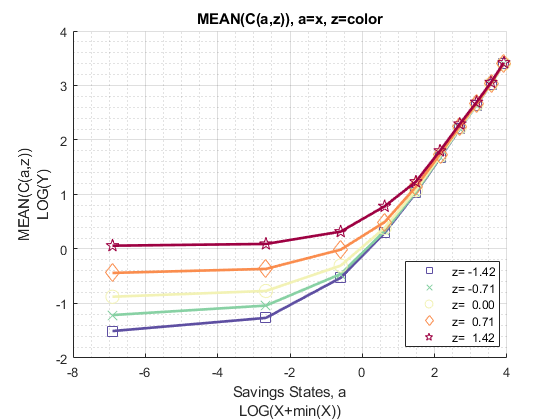

mp_support_graph('cl_st_graph_title') = {'MEAN(C(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(KM,J))", V_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mn_age_19    mn_age_28    mn_age_44    mn_age_60    mn_age_76    mn_age_92    mn_age_100
    _____    ____    _____    _________    _________    _________    _________    _________    _________    __________

      1       1        0       2.7883        2.8117       2.6288       2.1735       1.5677       1.4867       1.5251  
      2       2        0        2.579        1.8628       1.9631       1.7018       1.1819       1.1375       1.1785  
      3       3        0       1.8686        1.2776        1.405       1.2449      0.86018      0.92791      0.97581  
      4       

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(KM,J))", ap_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mn_age_19    mn_age_28    mn_age_44    mn_age_60    mn_age_76    mn_age_92    mn_age_100
    _____    ____    _____    _________    _________    _________    _________    _________    _________    __________

      1       1        0       11.826           11       9.9029       8.7329       5.0157       0.33265         0     
      2       2        0       11.826           11       9.9029       8.7329       5.0157       0.33265         0     
      3       3        0       11.826           11       9.9029       8.7329       5.0157       0.33265         0     
      4       1

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(KM,J))", cons_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mn_age_19    mn_age_28    mn_age_44    mn_age_60    mn_age_76    mn_age_92    mn_age_100
    _____    ____    _____    _________    _________    _________    _________    _________    _________    __________

      1       1        0       3.6518       4.4776       5.8075       6.9469       9.9458       14.629        14.961  
      2       2        0       3.6518       4.4776       5.8075       6.9469       9.9458       14.629        14.961  
      3       3        0       3.6518       4.4776       5.8075       6.9469       9.9458       14.629        14.961  
      4       1 

Graph Mean Values:

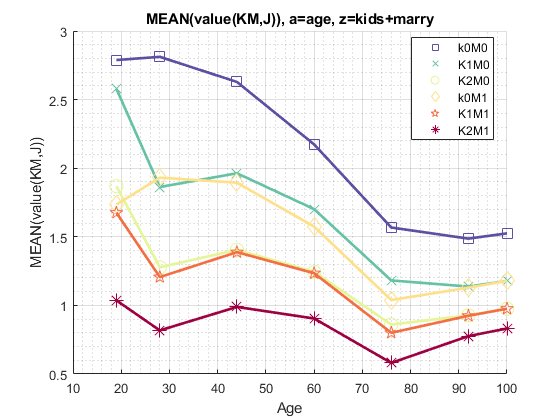

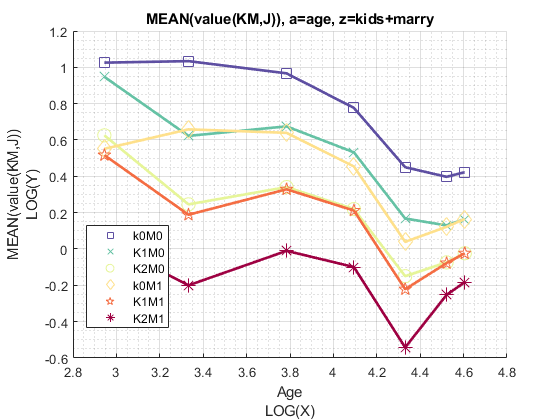

mp_support_graph('cl_st_graph_title') = {'MEAN(value(KM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

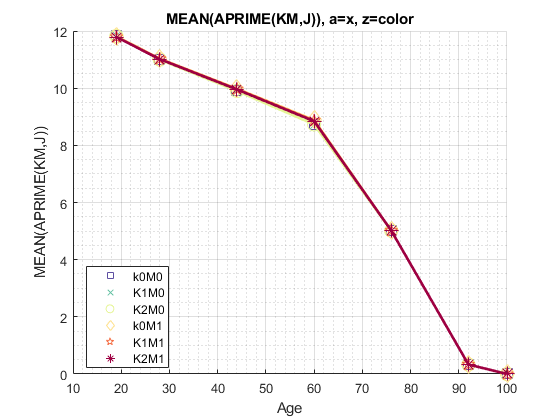

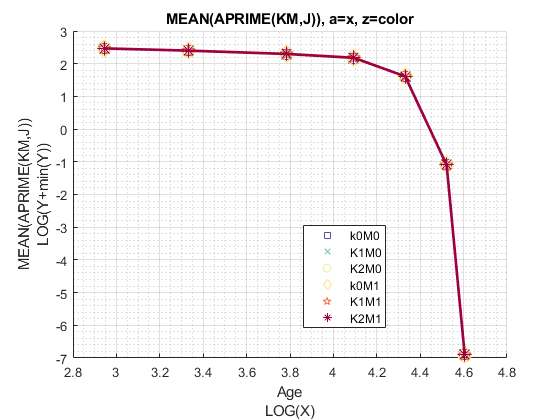

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(KM,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

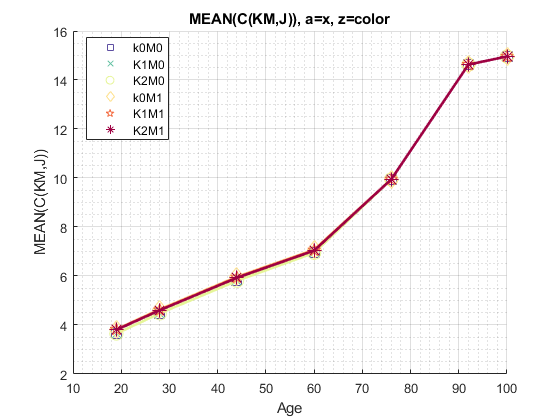

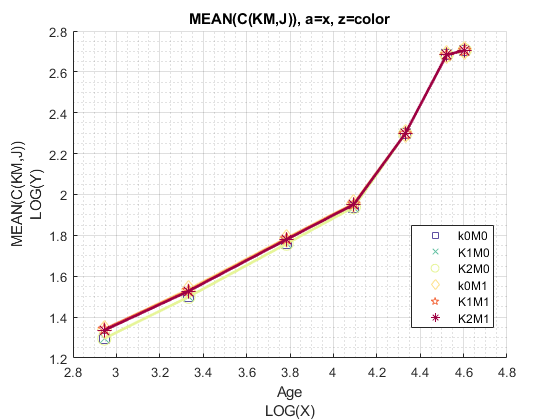

mp_support_graph('cl_st_graph_title') = {'MEAN(C(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);